# The Harmonic Series

Dr. Matthew Nokleby, Wayne State University. ECE 4330 Winter 2018.

Let's take some time to get used to the harmonic functions that underly the Fourier series expansion of a periodic signal. For a particular fundamental frequency, the harmonic functions are sinusoids at every integer multiple of that frequency. Let's first look at the 0th, 1st, 2nd, and 3rd harmonic. Remember that these are complex signals, so we'll plot the real and imaginary parts on the same axis

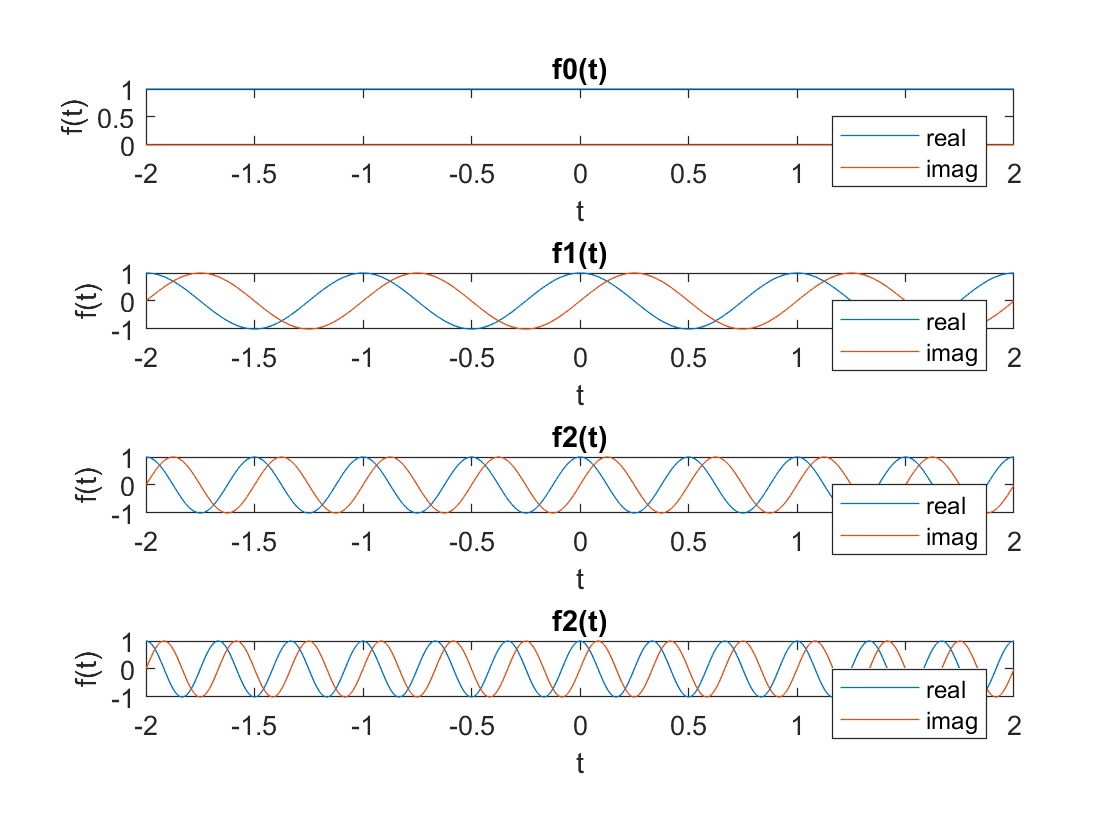

SAMPLE_RATE = 44100; %in hz, or samples per second
omega = 2*pi; %in rad/sec
Tmin = -2;
Tmax = 2;
tValues = Tmin:1/SAMPLE_RATE:Tmax;

%HINT: (MATLAB likes you to use '1i' as the imaginary unit so you don't confuse it with a for loop counter!)
f0 = exp(1i*0*omega*tValues); 
f1 = exp(1i*1*omega*tValues);
f2 = exp(1i*2*omega*tValues);
f3 = exp(1i*3*omega*tValues);

close all;
subplot(4,1,1);
plot(tValues,real(f0),tValues,imag(f0));
xlabel('t');
ylabel('f(t)');
title('f0(t)');
legend('real','imag');

subplot(4,1,2);
plot(tValues,real(f1),tValues,imag(f1));
xlabel('t');
ylabel('f(t)');
title('f1(t)');
legend('real','imag');

subplot(4,1,3);
plot(tValues,real(f2),tValues,imag(f2));
xlabel('t');
ylabel('f(t)');
title('f2(t)');
legend('real','imag');

subplot(4,1,4);
plot(tValues,real(f3),tValues,imag(f3));
xlabel('t');
ylabel('f(t)');
title('f2(t)');
legend('real','imag');

Why is f0(t) so boring?

Now, let's try *listening* to the harmonics. We'll pick a higher fundamental frequency for more sensible audio.

omega = 2*pi*110; %in rad/sec
DURATION = 2;
tValues = 0:1/SAMPLE_RATE:DURATION;

f0 = exp(1i*0*omega*tValues); 
f1 = exp(1i*1*omega*tValues);
f2 = exp(1i*2*omega*tValues);
f3 = exp(1i*3*omega*tValues);

%Only listen to the   real part
%sound(real(f0),SAMPLE_RATE);
%sound(real(f1),SAMPLE_RATE);
%sound(real(f2),SAMPLE_RATE);
sound(real(f3),SAMPLE_RATE);

What do you hear? The 0th harmonic is hardly a sound at all. It's a DC signal, and the human ear doesn't process very low frequency signals as noise at all. (A DC "sound wave" is more like air pressure than anything else.) The first harmonic is a pure tone at 55hz, which is the note A on a musical scale. The second harmonic is the same tone, but one octave up; it's also an A. What about the third harmonic? You might expect it to be an A yet another octave up, but it's not. Your ear perceives two waves as the same note only if the frequency of the two notes is related by doubling or a higher power of two. 110Hz is twice 55Hz, but 165Hz is not twice 110Hz. In fact, the third harmonic is another note entirely---in this case an E.

We can go even further, and each new harmonic will give us a new musical note. Can you tell which ones will be repeats of previous notes by thinking about powers of two?

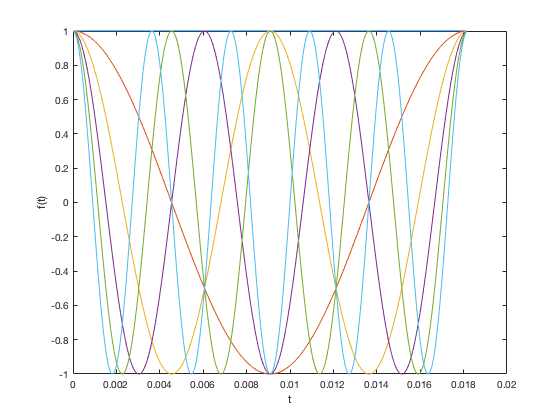

omega = 2*pi*55; %in rad/sec
DURATION = 2;
tValues = 0:1/SAMPLE_RATE:DURATION;
five_periods = length(0:1/SAMPLE_RATE:2*pi/omega);

NUMBER_OF_HARMONICS = 5;

close all;
for i=0:NUMBER_OF_HARMONICS
    f = exp(1i*i*omega*tValues);
    sound(real(f),SAMPLE_RATE);
    plot(tValues(1:five_periods),real(f(1:five_periods)));
    xlabel('t');
    ylabel('f(t)');
    hold on;
    pause;
end %for i

In both music theory and audio processing, the sequence of notes we heard is called the "overtone series". In this case, the new notes in order are A, E, C#, G, B, and so on for all twelve musical notes.

In real-world audio, the overtones give "color" to periodic signals. A note is rarely a pure sinusoid, but a combination of a fundamental sinusoid with overtones at each harmonic. Let's see what a combination of overtones looks and sounds like.

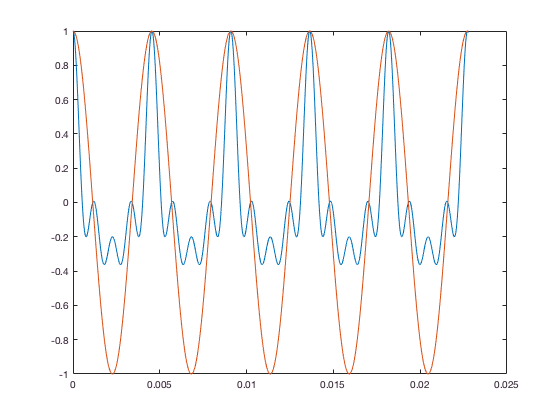

omega = 2*pi*220; %in rad/sec
DURATION = 2;
tValues = 0:1/SAMPLE_RATE:DURATION;
five_periods = 5*length(0:1/SAMPLE_RATE:2*pi/omega);

D = [1 1/2 1/2 1/2]; %Weighted combination of sinusoids at harmonic frequencies
f = zeros(1,length(tValues));
for i=1:length(D)
    f = f + D(i)*real(exp(1i*i*omega*tValues));
end %for i
f = f./max(f);


close all;
plot(tValues(1:five_periods),f(1:five_periods),tValues(1:five_periods),real(exp(1i*omega*tValues(1:five_periods))));

sound(f,SAMPLE_RATE);